# Using Casadi for Collision Avoidance OCP

This is a re-implementation of ex1_static_obstacle with a new vehicle-tire model (9-state, more realistic).

The vehicle body is a 3DOF planar body, the tire model is a smoothed Dugoff model (see Draft 2 for details).

Some ideas on debugging Casadi/IPOPT solver failure:

- Tune (increase) the problem discretization level;

- Soften the constraints (especially the dynamic equality constraints) by adding a slack variable;

addpath('C:\Program Files\casadi-windows-matlabR2016a-v3.5.5');
import casadi.*

OCP = colliOCPv2(50);
OCP.build_basics();
% manually change the collision criteria
OCP.R_col = 2.04; % collision radius (larger than 2 to fit the ziegler circle definition)
OCP.build_debug_var(); % for debug, run this function
OCP.add_control_bounds(); % use default bounds
% OCP.add_initial_conditions(); % use default I.C.'s
v_xb0 = 5; v_yb0 = 0; px0 = 0; py0 = 5; r0 = 0; psi0 = 0; omega_f0 = 30; omega_r0 = 30; delta0 = 0;
OCP.add_initial_conditions(v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0); % driving straight
% OCP.add_initial_conditions(5,0,0,5,5,0,30,30,0); % initially spinning
OCP.add_path_constraints(); % use default constraints
OCP.add_ego_centers();
OCP.add_obstacle_centers(); % use default static obstacle
OCP.add_collision_constraint();
OCP.add_terminal_conditions(); % default T.C.'s
% OCP.modify_objective(); % add obstacle CG repulsion into the objective.
OCP.set_solver_init();
% OCP.warm_start_init(sol);
sol = OCP.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1709
Number of nonzeros in inequality constraint Jacobian.:      586
Number of nonzeros in Lagrangian Hessian.............:      985

Total number of variables............................:      229
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      189
Total number of inequality constraints...............:      271
        inequality constraints with only lower bounds:      189
   inequality constraints with lower and upper bounds:       82
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 8

If the solver has a solution, we can visualize the states, intermediate variables, controls.

If the solver failed, we can still use opti.debug.value() to investigate the values of variables.

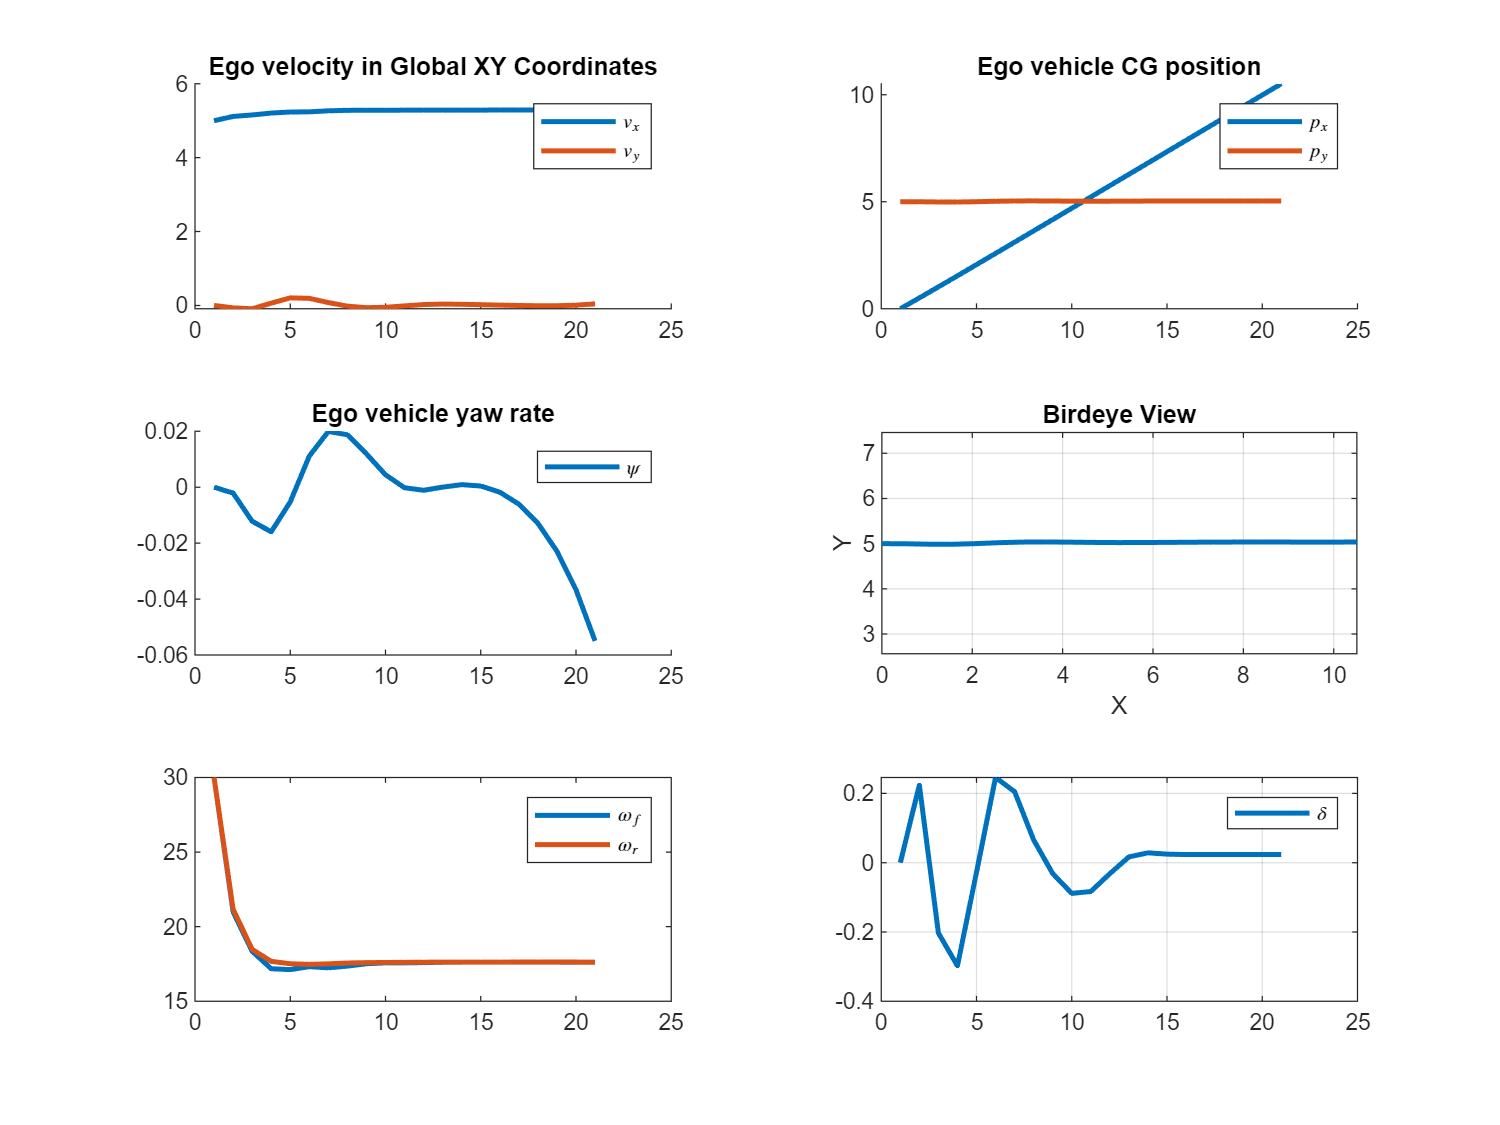

% if solutin is found, set foundSol = true. Otherwise set foundSol = false, and 
% the debug results will be used instead.
foundSol = true;
basic_plots(OCP,sol,foundSol);

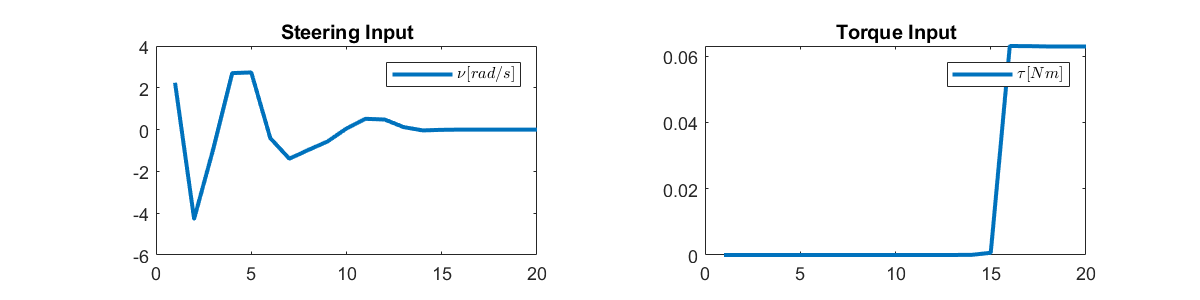

controls_plot(OCP,sol,foundSol)

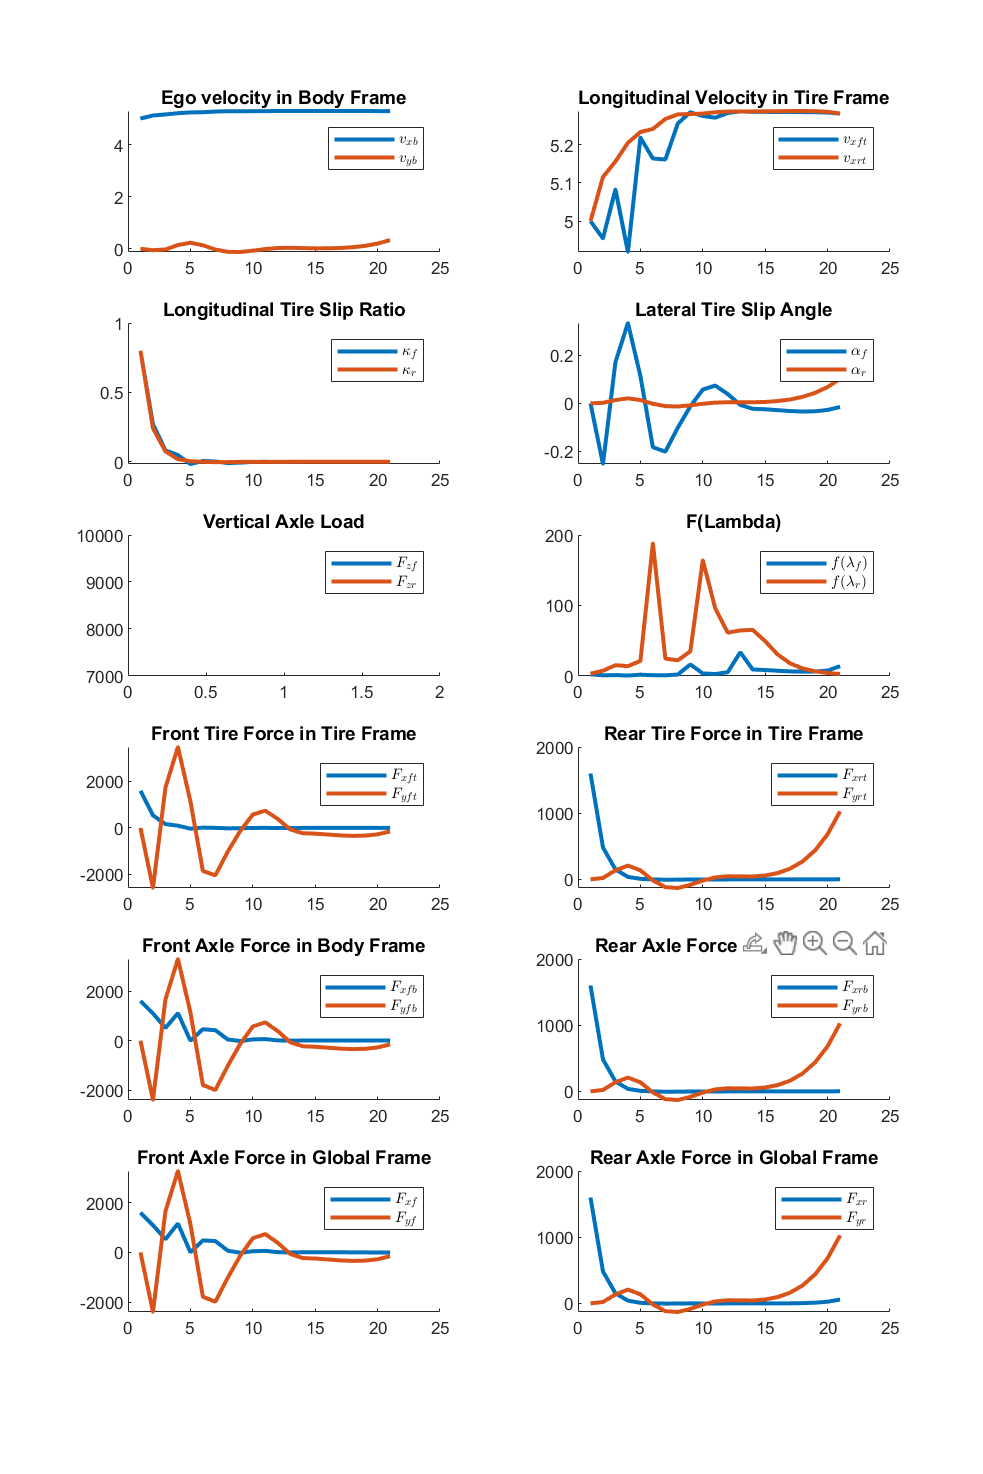

debug_plot(OCP,sol,foundSol)

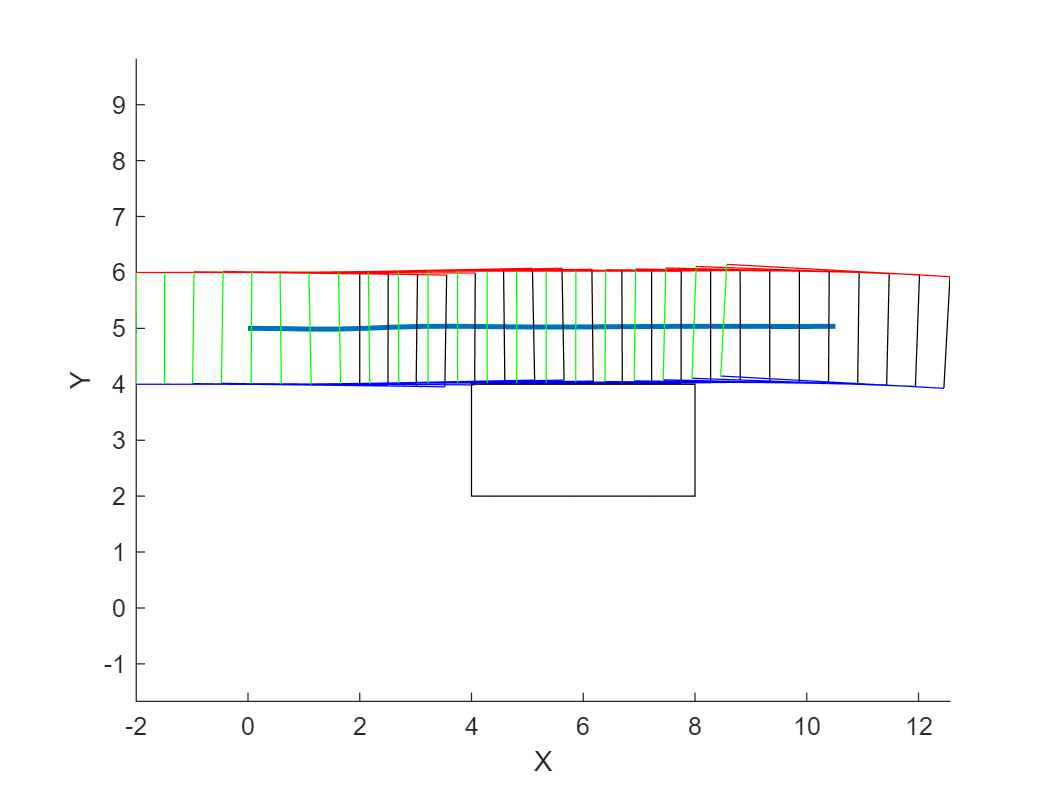

% overlap the vehicle body frame by frame onto the results
figure();
if ~foundSol
    sol = OCP.opti.debug;
end
hold on;
plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
X_c_arr = sol.value(OCP.px);
Y_c_arr = sol.value(OCP.py);
psi_arr = sol.value(OCP.psi);

for i = 1:length(sol.value(OCP.px))
    drawVehicleBox(X_c_arr(i),Y_c_arr(i),psi_arr(i),4,2);
end
rectangle('Position',[OCP.x_a 2 4 2]);
xlabel('X'); ylabel('Y')
axis equal

Use the 3-circle representation:

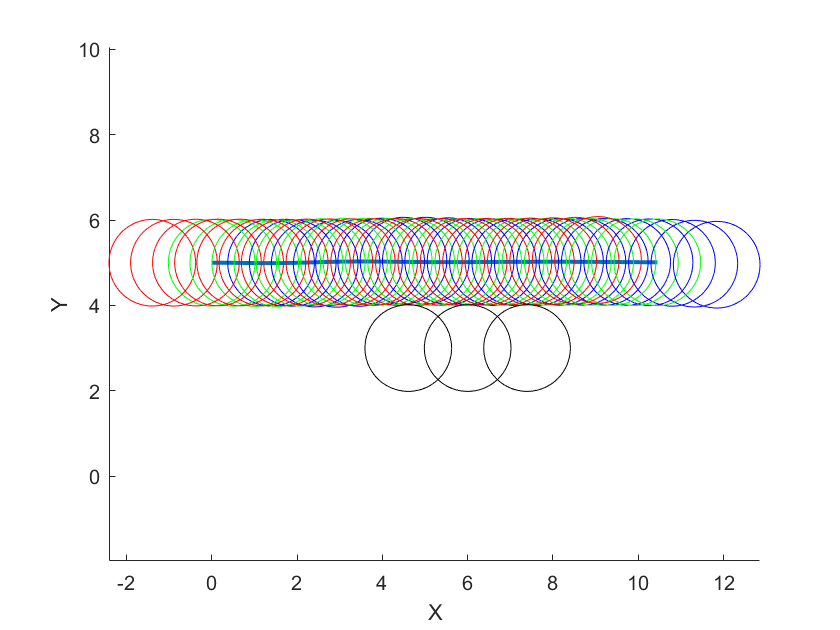

circles_overlap(OCP,sol,foundSol);

Make a video

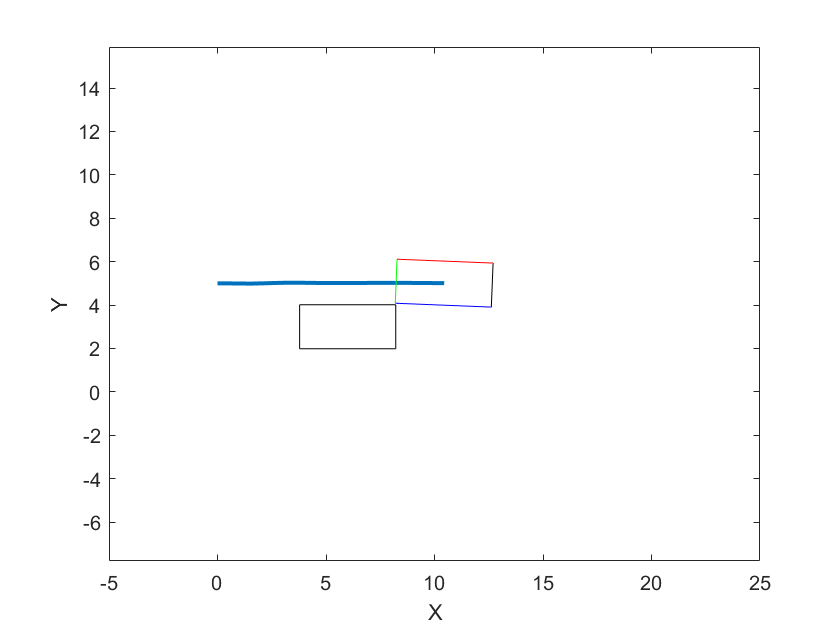

videoName = 'linear_tire_static_obstacle';
make_video_rectangles(OCP,sol,videoName,foundSol)

Helper functions (you may want to group these helper functions into a class later)

function ClearLinesFromAxes()
  axesHandlesToChildObjects = findobj(gca, 'Type', 'line');
  if ~isempty(axesHandlesToChildObjects)
    delete(axesHandlesToChildObjects);
  end  
end

function basic_plots(OCP,sol,foundSol)
    %basic_plots Plot the basic system states
    if ~foundSol
        sol = OCP.opti.debug;
    end

    figure('Position',[100 100 800 600]);
    tiledlayout(3,2)
    nexttile;
    hold on
    plot(sol.value(OCP.vx),'LineWidth',2);
    plot(sol.value(OCP.vy),'LineWidth',2);
    legend('$v_{x}$','$v_{y}$','interpreter','latex');
    title('Ego velocity in Global XY Coordinates')
    nexttile;
    hold on
    plot(sol.value(OCP.px),'LineWidth',2);
    plot(sol.value(OCP.py),'LineWidth',2);
    legend('$p_x$','$p_y$','interpreter','latex')
    title('Ego vehicle CG position');
    nexttile;
    hold on
    plot(sol.value(OCP.psi),'LineWidth',2);
    legend('$\psi$','interpreter','latex')
    title('Ego vehicle yaw rate')
    nexttile;
    plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
    xlabel('X'); ylabel('Y'); axis equal; grid on;
    title('Birdeye View');
    obs_colors = zeros(4,3); % obstacle color: all black
    Xobs_c_arr = sol.value(OCP.px_obs);
    Yobs_c_arr = sol.value(OCP.py_obs);
    psiobs_c_arr = sol.value(OCP.psi_obs);
    for i = 1:length(OCP.px_obs)
        drawVehicleBox(Xobs_c_arr(i),Yobs_c_arr(i),psiobs_c_arr(i),OCP.a+OCP.b,OCP.R_col,obs_colors);
    end
    nexttile;
    plot(sol.value(OCP.omega_f),'LineWidth',2);
    hold on
    plot(sol.value(OCP.omega_r),'LineWidth',2);
    legend('$\omega_f$','$\omega_r$','interpreter','latex');
    nexttile;
    plot(sol.value(OCP.delta),'LineWidth',2);
    legend('$\delta$','interpreter','latex');
    grid on;
end

function controls_plot(OCP,sol,foundSol)
    %controls_plot Plot the control signals
    if ~foundSol
        sol = OCP.opti.debug;
    end
    figure('Position',[100 100 800 200])
    tiledlayout(1,2);
    nexttile
    plot(sol.value(OCP.nu),'LineWidth',2);
    title('Steering Input');
    legend('$\nu [rad/s]$','interpreter','latex')
    nexttile;
    plot(sol.value(OCP.tau),'LineWidth',2);
    title('Torque Input')
    legend('$\tau [Nm]$','interpreter','latex');
    title('Torque Input');
end

function debug_plot(OCP,sol,foundSol)
    %debug_plot Plot the debug signals
    if ~foundSol
        sol = OCP.opti.debug;
    end
    figure('Position',[100 100 800 1200]);
    tiledlayout(6,2)
    nexttile;
    hold on
    plot(sol.value(OCP.v_xb_dbg),'LineWidth',2);
    plot(sol.value(OCP.v_yb_dbg),'LineWidth',2);
    legend('$v_{xb}$','$v_{yb}$','interpreter','latex');
    title('Ego velocity in Body Frame')
    nexttile;
    hold on
    plot(sol.value(OCP.V_xft_dbg),'LineWidth',2);
    plot(sol.value(OCP.V_xrt_dbg),'LineWidth',2);
    legend('$v_{xft}$','$v_{xrt}$','interpreter','latex')
    title('Longitudinal Velocity in Tire Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.kappa_f_dbg),'LineWidth',2);
    plot(sol.value(OCP.kappa_r_dbg),'LineWidth',2);
    legend('$\kappa_{f}$','$\kappa_{r}$','interpreter','latex');
    title('Longitudinal Tire Slip Ratio')
    nexttile;
    hold on
    plot(sol.value(OCP.alpha_f_dbg),'LineWidth',2);
    plot(sol.value(OCP.alpha_r_dbg),'LineWidth',2);
    legend('$\alpha_{f}$','$\alpha_{r}$','interpreter','latex');
    title('Lateral Tire Slip Angle')
    nexttile;
    hold on
    plot(sol.value(OCP.F_zf_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_zr_dbg),'LineWidth',2);
    legend('$F_{zf}$','$F_{zr}$','interpreter','latex');
    title('Vertical Axle Load')
    nexttile;
    hold on
    plot(sol.value(OCP.flambda_f_dbg),'LineWidth',2);
    plot(sol.value(OCP.flambda_r_dbg),'LineWidth',2);
    legend('$f(\lambda_{f})$','$f(\lambda_{r})$','interpreter','latex');
    title('F(Lambda)');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xft_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yft_dbg),'LineWidth',2);
    legend('$F_{xft}$','$F_{yft}$','interpreter','latex');
    title('Front Tire Force in Tire Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xrt_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yrt_dbg),'LineWidth',2);
    legend('$F_{xrt}$','$F_{yrt}$','interpreter','latex');
    title('Rear Tire Force in Tire Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xfb_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yfb_dbg),'LineWidth',2);
    legend('$F_{xfb}$','$F_{yfb}$','interpreter','latex');
    title('Front Axle Force in Body Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xrb_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yrb_dbg),'LineWidth',2);
    legend('$F_{xrb}$','$F_{yrb}$','interpreter','latex');
    title('Rear Axle Force in Body Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xf_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yf_dbg),'LineWidth',2);
    legend('$F_{xf}$','$F_{yf}$','interpreter','latex');
    title('Front Axle Force in Global Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xr_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yr_dbg),'LineWidth',2);
    legend('$F_{xr}$','$F_{yr}$','interpreter','latex');
    title('Rear Axle Force in Global Frame');
end

function rectangle_overlap(OCP,sol,foundSol)
    %rectangle_overlap Draw the ego-obstacle vehicles rectangles in overlap
    if ~foundSol
        sol = OCP.opti.debug;
    end
    hFigure = figure();
    hold on;
    plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
    X_c_arr = sol.value(OCP.px);
    Y_c_arr = sol.value(OCP.py);
    psi_arr = sol.value(OCP.psi);
    Xobs_c = sol.value(OCP.x_b);
    Yobs_c = sol.value(OCP.y_b);
    psiobs_c = 0;
    
    obs_colors = zeros(4,3); % obstacle color: all black
    for i = 1:length(sol.value(OCP.px))
        drawVehicleBox(X_c_arr(i),Y_c_arr(i),psi_arr(i),OCP.a+OCP.b,OCP.R_col);
        drawVehicleBox(Xobs_c,Yobs_c,psiobs_c,OCP.a+OCP.b,OCP.R_col,obs_colors);
    end
    
    xlabel('X'); ylabel('Y')
    axis equal
end

function make_video_rectangles(OCP,sol,videoName,foundSol)
    %make_video_rectangles Make a video with the name videoName
    %   make_video_rectangles(OCP,sol,videoName)
    if ~foundSol
        sol = OCP.opti.debug;
    end
    v = VideoWriter([videoName '.avi']);
    v.FrameRate = 10;
    open(v);
    hFigure = figure();
    hold on;
    X_c_arr = sol.value(OCP.px);
    Y_c_arr = sol.value(OCP.py);
    psi_arr = sol.value(OCP.psi);
    Xobs_c = sol.value(OCP.x_b);
    Yobs_c = sol.value(OCP.y_b);
    psiobs_c = 0;
    obs_colors = zeros(4,3); % obstacle color: all black

    for i = 1:length(sol.value(OCP.px))
        plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
        hold on;
        drawVehicleBox(X_c_arr(i),Y_c_arr(i),psi_arr(i),OCP.a+OCP.b+OCP.R_col,OCP.R_col);
        drawVehicleBox(Xobs_c,Yobs_c,psiobs_c,OCP.a+OCP.b+OCP.R_col,OCP.R_col,obs_colors);
        %drawVehicleBox(Xobs_c_arr(i),Yobs_c_arr(i),psiobs_c_arr(i),OCP.a+OCP.b+OCP.R_col,OCP.R_col,obs_colors);
    
        xlim([-5, 25]);
        ylim([-5, 15]);
        xlabel('X'); ylabel('Y')
        axis equal;
        frame = getframe(hFigure);
        writeVideo(v,frame);
        hold off;
        %ClearLinesFromAxes(); % delete all line objects
    end
    close(v);
end

function circles_overlap(OCP,sol,foundSol)
    %circles_overlap Draw the ego-obstacle vehicles Ziegler 3-circles in overlap
    if ~foundSol
        sol = OCP.opti.debug;
    end
    hFigure = figure();
    hold on;
    plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
    X_c_arr = sol.value(OCP.px);
    Y_c_arr = sol.value(OCP.py);
    psi_arr = sol.value(OCP.psi);
    Xobs_c = sol.value(OCP.x_b);
    Yobs_c = sol.value(OCP.y_b);
    psiobs_c = 0;
    
    obs_colors = zeros(3,3); % obstacle color: all black
    for i = 1:length(sol.value(OCP.px))
        drawVehicleCircles(X_c_arr(i),Y_c_arr(i),psi_arr(i),OCP.a,OCP.R_col/2);
    end
    drawVehicleCircles(Xobs_c,Yobs_c,psiobs_c,OCP.a,OCP.R_col/2,obs_colors);
    
    xlabel('X'); ylabel('Y')
    axis equal
end

function make_video_circles(OCP,sol,videoName)
    %make_video_circles Make a video with the name videoName
    %   make_video_circles(OCP,sol,videoName)
    v = VideoWriter([videoName '.avi']);
    v.FrameRate = 10;
    open(v);
    hFigure = figure();
    hold on;
    X_c_arr = sol.value(OCP.px);
    Y_c_arr = sol.value(OCP.py);
    psi_arr = sol.value(OCP.psi);
    Xobs_c_arr = sol.value(OCP.px_obs);
    Yobs_c_arr = sol.value(OCP.py_obs);
    psiobs_c_arr = sol.value(OCP.psi_obs);
    
    obs_colors = zeros(4,3); % obstacle color: all black
    for i = 1:length(sol.value(OCP.px))
        plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
        hold on;
        drawVehicleCircles(X_c_arr(i),Y_c_arr(i),psi_arr(i),OCP.a,OCP.R_col/2);
        drawVehicleCircles(Xobs_c_arr(i),Yobs_c_arr(i),psiobs_c_arr(i),OCP.a,OCP.R_col/2,obs_colors);  
        xlim([-5, 25]);
        ylim([-5, 15]);
        xlabel('X'); ylabel('Y')
        axis equal;
        frame = getframe(hFigure);
        writeVideo(v,frame);
        hold off;
        %ClearLinesFromAxes(); % delete all line objects
    end 
    close(v);
end